**Upload Data**

folder = fullfile('C:', 'Users', 'ariay', 'Desktop', 'Desktop', 'PHY293', '2-weight', 'PHY293 2-Weight', 'trials');

fileNames = {
    'trial8bottomleft.txt','trial8bottomright.txt', 'trial8left.txt', ...
    'trial9bottom.txt', 'trial9left.txt', ...
    'trial9secondtoright.txt', 'trial9topright.txt', 'trial10bottom.txt', ...
    'trial12mostright.txt', 'trial12top.txt'};

**Base Settings**

ptm = 0.12048; % microns per pixel
dt = 0.5; % time interval [s]
% Define an array of colors for each trial
colors = [
    1, 0, 0;  % Red
    1, 1, 1;  % Black
    0, 0, 1;  % Blue
    0, 1, 1;  % Cyan
    1, 0, 1;  % Magenta
    1, 1, 0;  % Yellow
    0.5, 0.5, 0.5;  % Gray
    0.5, 0, 0.5;    % Purple
    0, 0.5, 0.5;    % Teal
    0.5, 0.5, 0      % Olive
];

% Initialize cell arrays to store cumulative squared distances & slopes
cumulative_distances = cell(1, length(fileNames)); 
slopes = zeros(1, length(fileNames)); % Array to store slope for each trial
all_step_distances = [];


**Loop over each file and calculate squared distance traveled as a function of time**

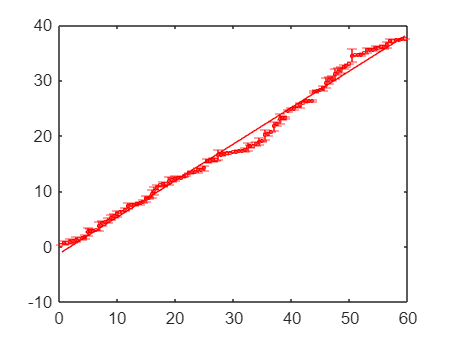

Unrecognized function or variable 'uncertainties'.

figure;
for k = 1:length(fileNames)
    % Load data
    filename = fullfile(folder, fileNames{k});
    opts = detectImportOptions(filename, 'NumHeaderLines', 2); 
    data = readtable(filename, opts);
    x = data{:, 1} * ptm; % unit conversion
    y = data{:, 2} * ptm; 

    % Calculate r^2 & r for each step
    dx = diff(x);
    dy = diff(y);
    r_squared = dx.^2 + dy.^2;
    r = sqrt(r_squared); 

    % Define time vector based on length of r_squared
    time_vector = (1:length(r_squared)) * dt; 
    
    % Cumulative squared distance for MSD
    cumulative_distances{k} = cumsum(r_squared);
    all_step_distances = [all_step_distances, r'];  % Concatenate step distances for histogram (r' = transpose r, column to row vector)

    % Fit a linear model to the MSD for this trial
    p = polyfit(time_vector, cumulative_distances{k}, 1); % Linear fit
    slopes(k) = p(1); % Store the slope (p(1)) for this trial

    %Plot MSD for each file
    legend('show','Location', 'southeast');
    errorbar(time_vector, cumulative_distances{k}, dy','o', 'MarkerSize', 2, 'DisplayName', sprintf('Trial %d', k), 'Color', colors(k, :));
    hold on;
    lin_fit = p(1) .* time_vector + p(2);
    % Plot cumulative squared distance traveled for each file
    plot(time_vector, lin_fit, 'LineStyle', '-', 'Color', colors(k, :), 'HandleVisibility', 'off');
    fprintf('Trial:%d, m = %.4f\n, ± %.4f\n', k, slopes(k), uncertainties(k));
end

**Plot Average Linear Fit**

plot(time_vector, polyval(p, time_vector), 'LineWidth', 1.5, 'DisplayName', 'Average Linear Fit', 'Color', 'green', 'LineStyle', '-');
xlabel('Time (s)');
ylabel('Mean Squared Displacement (\mum^2)');
title('Mean Squared Displacement vs Time for Each Trial');
hold off;

**Calculations for Part 1, Method 1: Eistein w fitted Drag Coefficient**

% Avg Drag Coefficient
D_Einstein = mean(slopes) / 4 * 1e-12 %[m^2/s]D = slope / 4 for 2D diffusion
% k
T = 296.5; %+/-0.1 Kelvin
r = 0.95 * 1e-6; %+/10^-7 meters (diamter/2, 1.95/2)
eta = 0.961 * 0.001; %Pa*s adjusted eta based off of 298K
gamma = 6 * pi * eta * r; %γ = 6πηr, η=8.9e-4, r=v1e-6
k_Einstein = D_Einstein * gamma / T
% N_A
N_A_Einstein = 8.314/k_Einstein


**Part 2: Method 2: Rayleigh w Fitted Histogram**

[h_counts, edges] = histcounts(all_step_distances * 1e-6, 'Normalization', 'pdf', 'NumBins', 50);  
bin_centers = edges(1:end-1) + diff(edges)/2;


Fit function to histogram data

fit_func = fittype('r/(2*D*t) * exp(-r^2/(4*D*t))', 'independent', 'r', 'coefficients', {'D', 't'});
initial_D = 2.4509e-13; % Initial guess for D
initial_t = dt;      % Initial guess for t
[fit_result, gof, output] = fit(bin_centers(:), h_counts(:), fit_func, 'StartPoint', [initial_D, initial_t]);

% Covariance matrix from the fit output
cov_matrix = output.covariance; 

% Uncertainty in D
D_uncertainty = sqrt(cov_matrix(1, 1)); % Variance of D is in (1, 1)

D_Histogram = fit_result.D
k_Histogram = D_Histogram * gamma / T
N_A_Histogram = 8.314 / k_Histogram


**Plot the histogram with the fitted Rayleigh distribution**

figure;
histogram(all_step_distances * 1e-6, 'Normalization', 'pdf', 'BinMethod', 'auto');
hold on;

% Overlay fitted Rayleigh distribution
r_values = linspace(min(bin_centers), max(bin_centers), 100); % Range of r values for fit
fitted_curve = feval(fit_result, r_values); % Evaluate the fitted Rayleigh function at r_values
plot(r_values, fitted_curve, 'r-', 'LineWidth', 2); % Plot the fitted curve

xlabel('Distance (m)');
ylabel('Probability Density');
title('Histogram of Step Distances with Rayleigh Fit');
legend('Histogram Data', 'Fitted Rayleigh Distribution');


**Part 2: Method 2: Max Likelihood w Fitted Histogram**

% Define the log-likelihood function for D
log_likelihood = @(D) -sum(log(all_step_distances * 1e-6 / (2 * D * dt)) - (all_step_distances * 1e-6).^2 / (4 * D * dt));

% Initial guess for D
initial_D = 2.4509e-13;

% Calculations
D_MLE = fminsearch(log_likelihood, initial_D)
k_MLE = D_MLE * gamma / T
N_A_MLE = 8.314 / k_MLE

max_likelihood_fitted = @(D) -sum(log(all_step_distances * 1e-6 / (2 * D * dt)) - (all_step_distances * 1e-6).^2 / (4 * D * dt));
% plot(r_values, max_likelihood_fitted, 'r-', 'LineWidth', 2); % Plot the fitted curve
hold off;
